# Newton Forward-Difference Polynomial Calculation

*Pouria Motahhari, Chemical and Petroleum Engineering Department, Fall 2022*

The provided code offers a method to approximate the value of a function at a specific point using the Newton forward-difference polynomial interpolation technique. By utilizing a set of discrete data points and a designated point of interest, this approach seeks to bridge the gap between discrete data and continuous functions. The code demonstrates the step-by-step process of constructing the forward-difference polynomial using finite differences and subsequent polynomial interpolation. Through this document, we will delve into the code's functionality, dissecting its key components and highlighting the underlying mathematical principles that enable the estimation of function values at desired points. Assume we have *x* and *f(x)* data. Then, using delta Operator ($\Delta \;$) :

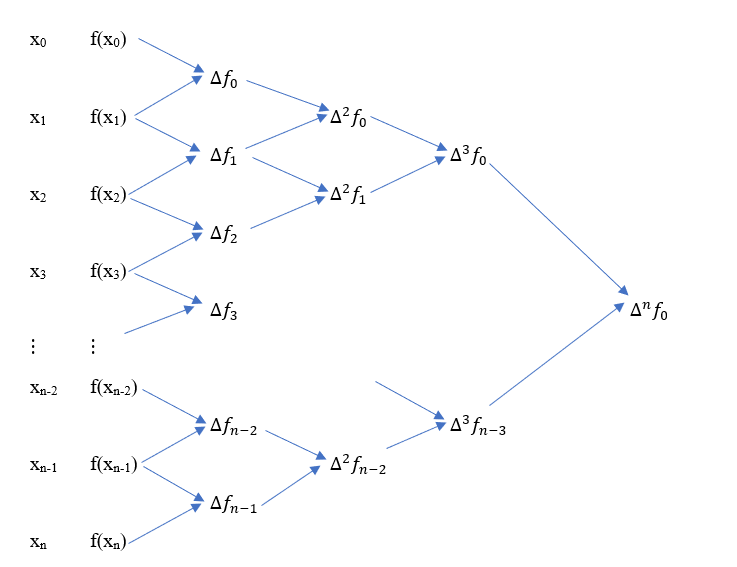

### Part1: Input data

clc, clear   % Clearing Workspace & Command Window
x=[1,2,3,4,5];   %This is a sample. you can change x'es (but you must have constant interval)
h=1;
f=[11;36;83;158;267];  %This is a sample. you can change f's
asked_x= input('Enter the desired value of x: ');
n=length(f);
a=( asked_x-x(1) )/h;  %alpha value for newton polynomial

### Part2: Calculating Delta's Array (Newton backward-difference polynomial)

deltaf=[f, zeros( n,n-1 )];

for i=2:n
    for j=1: n+1-i
        deltaf(j,i)= deltaf( j+1,i-1 )- deltaf( j,i-1 ); %delta^n(f) calculation
    end
end

### Part3: Calculating Newton Forward-Difference Polynomial sum (ANSWER)

forward_sum=f(1); %first term of forward newton polynomial (this variable is our answer)

%calculation for terms 1 to n 
for k=2:n

    fact_part=1;
    for l=0:k-2
        fact_part= fact_part*(a-l);
    end

    term=( deltaf(1,k)/ factorial(k-1) ) * fact_part;
    forward_sum= forward_sum+term ;
end

disp('The answer is: '), disp(forward_sum)

The answer is: 
  124.2560

